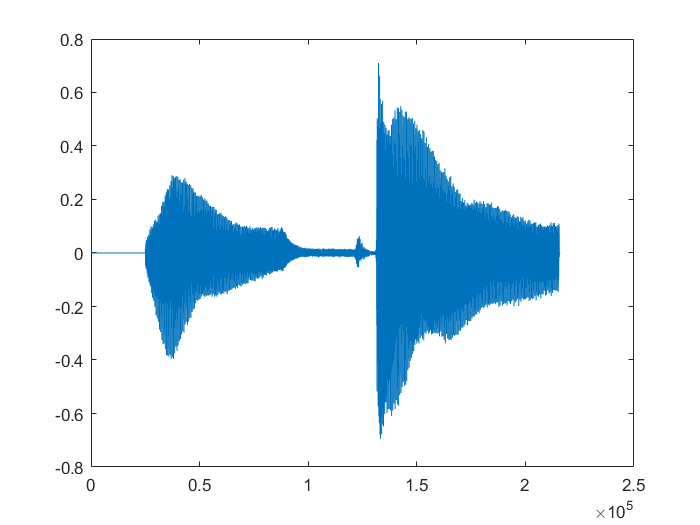

clc, clear

[y,fs]=audioread("6.mp3");

sound(y,fs)

plot(y)

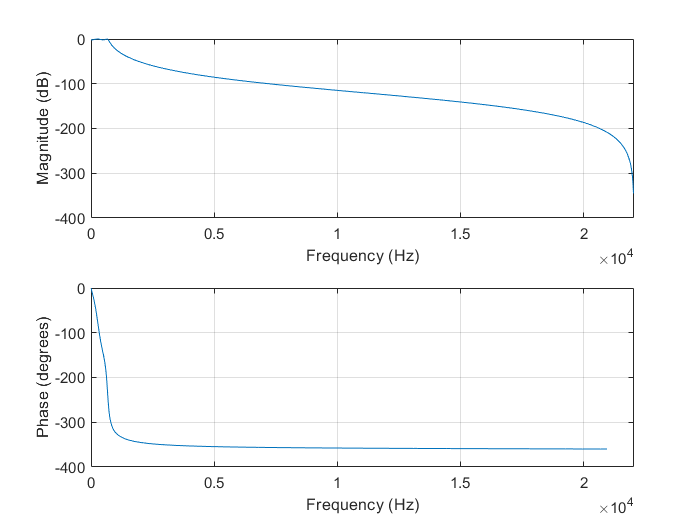


dp = 2;
f = 700;
Wp= f/(fs/2);
[b, a] = cheby1(4,dp,Wp,'low');
freqz(b,a,1024, fs)

y1= filter(b,a,y);

g=fft(y1);
potencia=abs(g).^2;
df=1/(length(y)/fs);
f=(0:length(y)-1)*df; 
[pks,locs]=findpeaks(potencia,"SortStr","descend","NPeaks",7);
fn = min(f(locs))

fn = 82.0568

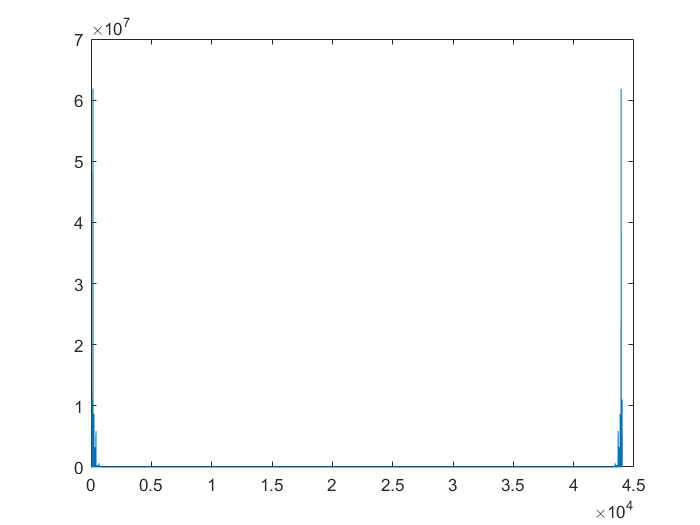


plot(f,potencia)

% axis([0 700 0 pks*1.2])
% xlabel('Frecuencia')
% ylabel('Potencia espectral')
% 
% L = 0.02*fs;
% overlap = floor(0.9*L);
% nfft = 2^nextpow2(L);
% [pxx,f] = pwelch(y1,hamming(L),overlap,nfft,fs);
% [pks, locs] = findpeaks(pxx,'SortStr','descend','NPeaks',1);
% sort(f(locs))